# Lab session IV:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 3 points

- Exercise 3: 3 points

- Exercise 4: 3 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to 

# Exercise 1:

The point p has coordinates

p_A = [3, 4]';

on a frame {A}, and coordinates

p_B = [-2.5, 0.5]';

on a frame {B}.

It is known that the angle between $x$-axis of frame {A} and the$y$ axes of the frame {B} is 30 deg counterclockwise.

##  1.1 Which are the coordinates of the origin of A seen from B?

ang=60

ang = 60

bRa=[cosd(ang) -sind(ang);sind(ang) cosd(ang)];
bDba=p_B-bRa*p_A

bDba =    -0.5359
   -4.0981


##  1.2 Which are the coordinates of the origin of B seen from A?

ang=-60

ang = -60

aRb=[cosd(ang) -sind(ang);sind(ang) cosd(ang)];
aDab=p_A-aRb*p_B

aDab =     3.8170
    1.5849


##  1.3 Which are the coordinates of a point q expressed in A if 

q_B = [3,1]';
aP=aRb*q_B+aDab

aP =     6.1830
   -0.5131


# Exercise 2:

 Let {A}, {B} and {C}, be 3 different reference frames. From them we know that:

- The origin of B with respect A is

AoB = [3,1,-2]';

- The origin of C with respect B is

BoC = [-3, 1,-2]';

- The three frames has different orientations in space. In fact:  

- The set of Euler angles stored in $\eta$ as $\eta = (\psi,\theta,\phi)$

eta = [25;145;30]; % Expressed in degrees

                 represent 3 consecutive rotations about z, y, and x respectively that allows to transform vectors from {A} to {B}

- The quaternion

q = 1/7*[-sqrt(3)*3.5;3;-1;-1.5];

                 allows to express in {B} a vector defined in {C}, if {C} and {B} had the same origin

Let in addition v1 and v2 to be points which coordinates are known in  {C}.

v1_C = [0;2;0];
v2_C = [0;2;5];

With the information provided above determine:

##  2.1.1 The affine** expression** that allows to relate a vector originally given in {C} to {B}. Note that no calculations have to be provided here, only the expression which is not a matrix.

-Bp=BRC*Cp+BdBC

BRC es la matriz de rotación que nos permite rotar un punto del frame C al frame B.

Cp es un punto expresado en el frame C.

BdBC es la distancia que hay del frame B al frame C visto desde B.

Bp es el punto que se obtiene de hacer las operaciones, punto en el frame B.

## 2.1.2 Implement a function called rotVbyq that provided a vector and a quaternion rotates the vector using quaternion multiplications. Test it and commet why do you think it is well implemented.

result=rotVbyq(v1_C,q)

result =     0.2487
    0.5408
    0.8035


##  2.2 The affine matrix that allows to express a vector originally given in {C} to {A}.

aRb=eAngles2rotM(q(1),q(2),q(3));
bRc=rotquat(q);
aRc=aRb*bRc

aRc =     0.7545    0.0474   -0.6546
    0.5040    0.4081    0.5261
    0.3613   -0.8626    0.3540


## 2.3 The vectors v1_C and v2_C forms a segment. Make a 3d plot (plot3() in matlab), representing how the segment is seen on {A} in red, on {B} in blue and on {C} in green.

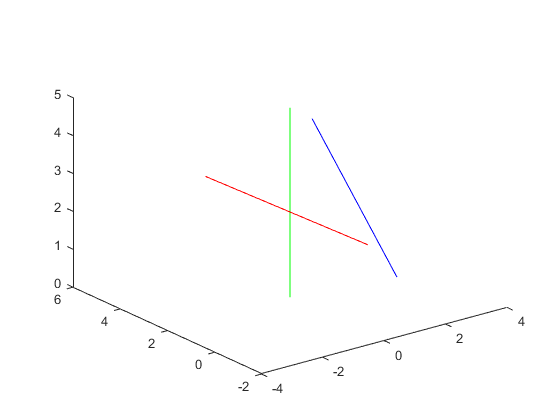

AoC=AoB+BoC;
Bp=bRc*v1_C-BoC;
Bp2=bRc*v2_C-BoC;
Ap=aRc*v1_C-AoC;
Ap2=aRc*v2_C-AoC;
plot3([Ap(1);Ap2(1)],[Ap(2);Ap2(2)],[Ap(3);Ap2(3)],'Color',[1,0,0])
hold on
plot3([Bp(1);Bp2(1)],[Bp(2);Bp2(2)],[Bp(3);Bp2(3)],'Color',[0,0,1])
plot3([v1_C(1);v2_C(1)],[v1_C(2);v2_C(2)],[v1_C(3);v2_C(3)],'Color',[0,1,0])
hold off

# Exercise 3:

The points described by the columns of the matrix A 

A = load('AEx3.mat');
A = A.A;

are points contained into a circle, and they are defined in a world frame W.

A camera is situated at point

wc = [1; 6; 1];

 defined in the world frame. Moreover the orientation of this camera frame is achieved by rotating the world frame 90 degs about its y axis followed by -20 degrees about the resulting z axis.

If the camera has a focal length of 1/34 m:

##  3.1 Make a plot with the view of the points of the circle projected into the camera plane.

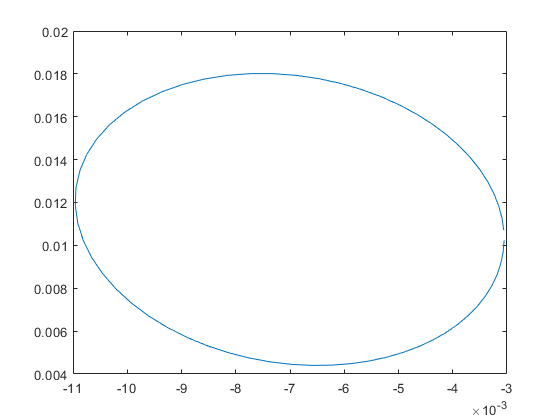

f=1/34;
u=[1,0,0];
angle=0;
u2=[0,1,0];
angle2=90;
u3=[0,0,1];
angle3=-20;
matrix=Eaa2rotMat(u,angle);
matrix2=Eaa2rotMat(u2,angle2);
matrix3=Eaa2rotMat(u3,angle3);
CRW=matrix'*matrix2'*matrix3';
CAW = [CRW -CRW*wc; 0 0 0 1];
result=cameraproj(CAW,f,A);
plot(result(1,:),result(2,:))

##  3.2 Make also a 3D plot where all the scene is drawn in the world coordinates. The scene must contain the 2 reference frames (2 orthogonal sets of vectors) and the circle points. 

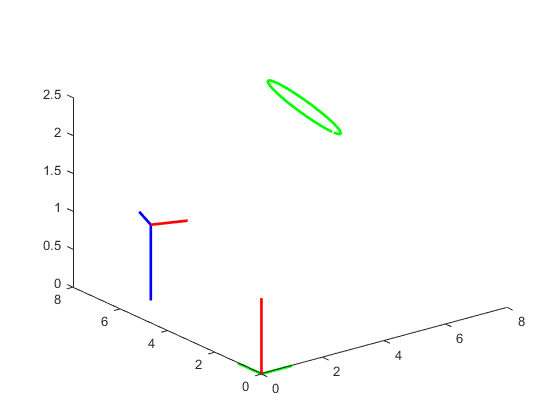

WAC = [CRW' wc; 0 0 0 1];
x = [1 0 0]';
y = [0 1 0]';
z= [0 0 1]';

o = [0;0;0];

wx = WAC*[x;1];
wx = wx(1:3);

wy = WAC*[y;1];
wy = wy(1:3);

wz = WAC*[z;1];
wz = wz(1:3);

wo = wc;
plot3([o(1);x(1)],[o(2);x(2)],[o(3);x(3)],'Color',[0,1,0],'LineWidth',2);
hold on;
plot3([o(1);y(1)],[o(2);y(2)],[o(3);y(3)],'Color',[0,1,0],'LineWidth',2);
plot3([o(1);z(1)],[o(2);z(2)],[o(3);z(3)],'Color',[1,0,0],'LineWidth',2);
plot3([wo(1);wx(1)],[wo(2);wx(2)],[wo(3);wx(3)],'Color',[0,0,1],'LineWidth',2);
plot3([wo(1);wy(1)],[wo(2);wy(2)],[wo(3);wy(3)],'Color',[0,0,1],'LineWidth',2);
plot3([wo(1);wz(1)],[wo(2);wz(2)],[wo(3);wz(3)],'Color',[1,0,0],'LineWidth',2);
plot3(A(1,:),A(2,:),A(3,:),'g','LineWidth',2);
hold off

You can use the provided function cameraproj.

# Exercise 4:

The columns of the next matrix, represents the coordinates od 4 points defined in a world frame.

A = load('AEx4.mat');
A = A.A;

From this 4 points, two segments are defined. The segment one, goes from the point defined by the first column to the point defined by the second column. The second segment is defined by the other two points.

 A camera frame is seeing the scene. The origin of the world frame seen from the camera frame is given by the vector

wc = [4.665;3.735;-0.5395];

And the orientation of the camera frame is obtained after rotating the world frame -150 degs about the direction

u = [0.01;-.2;1];

With the data provided determine:

## 4.1 The minimum angle that both segments forms (hint, they intersect)

## 4.2 The angle that both segments forms in the image plane

## 4.3 Deliver a 3D representation of the scene with all the coordinates refered to the world frame

## 4.4 Deliver the same 3D scene representations but with all the coordinates refered to the camera frame